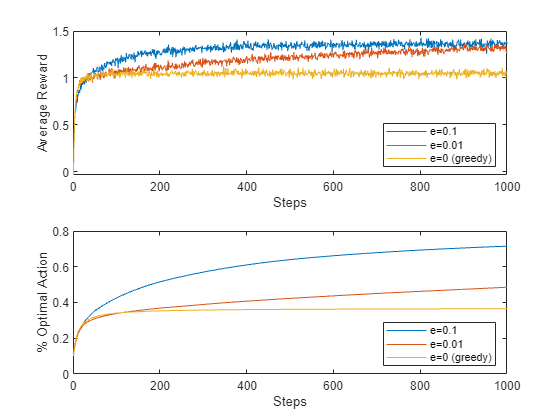

epsilons = [0.1 , 0.01 , 0.0];  % epsilons a probar fijos
Ravg = zeros(length(epsilons), 1000);  % almacena la recompensa promedio acumulada
optimal_m = zeros(length(epsilons), 1000);  % almacena la proporción acumulada de acciones óptimas seleccionadas

for i = 1:length(epsilons)
    epsilon = epsilons(i);
    for j = 1:2000
        mean_q_xa = randn(10,1);  % Vector de estimaciones iniciales de valor de las acciones
        [As, Q, R] = bandit(mean_q_xa, 1000, epsilon);
        Ravg(i, :) = Ravg(i, :) + R;  % acumula las recompensas obtenidas
        [~, max_ind] = max(mean_q_xa);
        optimal_m(i, :) = optimal_m(i, :) + cumsum(As == max_ind) ./ (1:1000);
    end

    subplot(2, 1, 1);
    plot(1:1000, Ravg(i, :) ./ 2000);
    hold on;

    subplot(2, 1, 2);
    plot(1:1000, optimal_m(i, :) ./ 2000);
    hold on;
end

subplot(2, 1, 1);
xlabel('Steps');
ylabel('Average Reward');
legend('e=0.1', 'e=0.01', 'e=0 (greedy)', 'Location', 'southeast');

subplot(2, 1, 2);
xlabel('Steps');
ylabel('% Optimal Action');
legend('e=0.1', 'e=0.01', 'e=0 (greedy)', 'Location', 'southeast');